# `LAB1:1.4（b）`

`朱泺源 12511622 罗玛 12510925`

`实验目标概括：`

    证明系统 y[n] = x[n] + x[n+1] 是非因果的。

`具体实验内容：`

`(1)题目解析`

因果系统的输出只与当前时刻及过去的输入有关，不能依赖未来的输入。

题目要求使用 x[n] = u[n] 来验证。

输入 x 定义在 -5 <= n <= 9，输出 y 定义在 -6 <= n <= 9。

若在某个时刻 n，输出 y[n] 用到了未来时刻 n+1 的输入，则系统非因果。

`(2)程序代码`

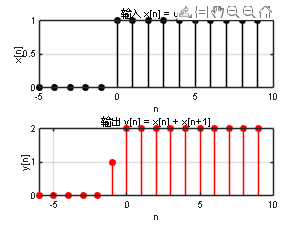

nx = -5:9;
x = double(nx >= 0);      %  u[n]


nxx = -6:10;
xt = double(nxx >= 0);   % 扩展后的 u[n]

ny = -6:9;

y=xt(1:end-1)+xt(2:end); % 两个信号相加


figure;
subplot(2,1,1);
stem(nx, x, 'k', 'filled');
xlabel('n'); ylabel('x[n]');
title('输入 x[n] = u[n]');
grid on;

subplot(2,1,2);
stem(ny, y, 'r', 'filled');
xlabel('n'); ylabel('y[n]');
title('输出 y[n] = x[n] + x[n+1]');
grid on;

`(3)结果图`

`(4)结果分析`

 n = -1 处，输入 x[-1] = 0，但输出 y[-1] = 1

还未输入就有输出，可见y[n]是非因果的

`经验总结：`

`@朱泺源>可以简单判断输出发生在输入前来判断因果性`

`@罗玛>要注意信号的时间轴`

`自我评价：`

`@朱泺源 10`

`@罗玛 10`